# Test deep learning model on multiple labeled animal images

## Objective: Classify types of wild animals from images

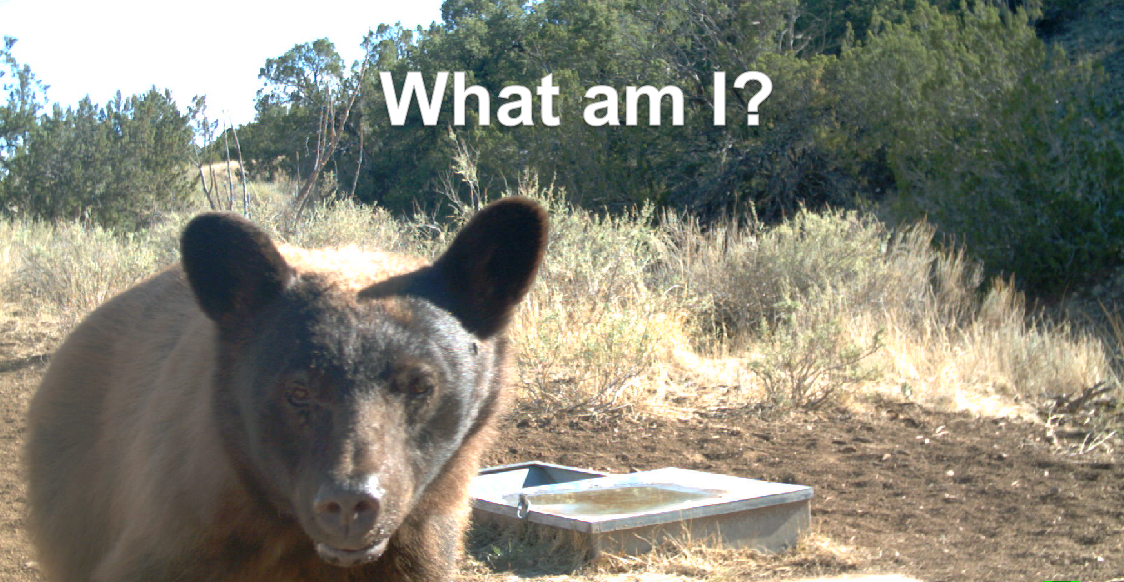

Article describing the example:

[https://www.mathworks.com/company/newsletters/articles/an-experiment-in-deep-learning-with-wild-animal-trail-camera-data.html](https://www.mathworks.com/company/newsletters/articles/an-experiment-in-deep-learning-with-wild-animal-trail-camera-data.html)

The model was trained using the following example with Inception v3 network: 

[https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html)

Details on Inception V3 architecture found in this paper: [https://arxiv.org/abs/1512.00567](https://arxiv.org/abs/1512.00567)

## Select and load network

To test the network, ***you'll need ***[`inceptionv3 `](https://www.mathworks.com/matlabcentral/fileexchange/65679-deep-learning-toolbox-model-for-inception-v3-network)***(from Add-on Explorer) ***

[https://www.mathworks.com/solutions/deep-learning/models.html](https://www.mathworks.com/solutions/deep-learning/models.html)

Hint: if you execute this line: `net = inceptionv3();` the error message will provide a link to the correct add-on ;)

### Choose type of model

Select the model to test:

- Bear/ not bear

- Barbary sheep vs bighorn sheep

- 40 types of animals

load("40AnimalsNetwork.mat")

## Classify new images

### Read image(s)

Pass image directories or list of files

% mydir = "../Animals";  
% ds = imageDatastore(mydir,"IncludeSubfolders",true,...
%     "LabelSource","foldernames"); 

(Use a list saved earlier, as in our case. Note, this file isn't in the repo)

load myfilelist fileList     

ds = imageDatastore(fileList.FileName,"IncludeSubfolders",true,...
    "Labels",fileList.Label); 

Split or choose number of images to test

rng(42)  % repeatable to test           
ds1 = splitEachLabel(ds,100);    % select n from each label

### Resize image(s) for network

Get the input size from the network and resize through `augmentedImageDatastore`:

inputSize = net.Layers(1).InputSize(1:2);
augds = augmentedImageDatastore(inputSize,ds1);

### Classify type of animal

Perform classification

Note: you may need to change labels to correctly assess

[predictedLabel,probs] = classify(net,augds);

actualLabel = ds1.Labels;   
accuracy = mean(predictedLabel == actualLabel)* 100;
testfilenames = ds1.Files;

Create a confusion matrix to compare results. (use a different test set

figure
confusionchart(actualLabel,predictedLabel);
title("Accuracy: "+string(accuracy)+ "%")

## Visualize some predictions

Select random images from datastore

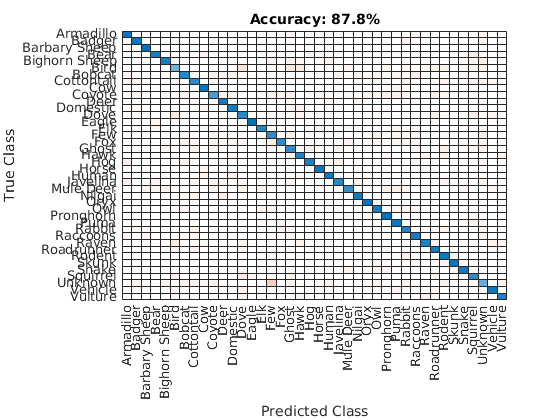

n = 6;
 
idx = randperm(numel(testfilenames),n);
figure
t = tiledlayout('flow');
for i = 1:n    
    I = readimage(ds1,idx(i));
    nexttile;
    imshow(I)

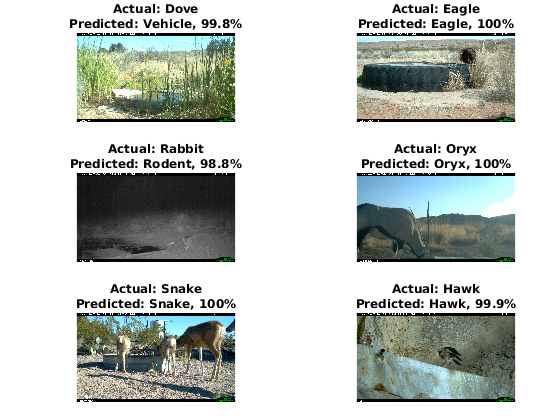

    label = predictedLabel(idx(i));
    actual = actualLabel(idx(i));
    title(["Actual: "+ string(actual), ...
        "Predicted: "+ string(label) + ", " + ...
        num2str(100*max(probs(idx(i),:)),3) + "%"],...
        "Interpreter","none");
end
% Remove spacing
t.TileSpacing = 'none';
t.Padding = 'none';